# Path Planning for Drone

Move 4 ft x 4 ft drone using RRT Planner

Load map of house 

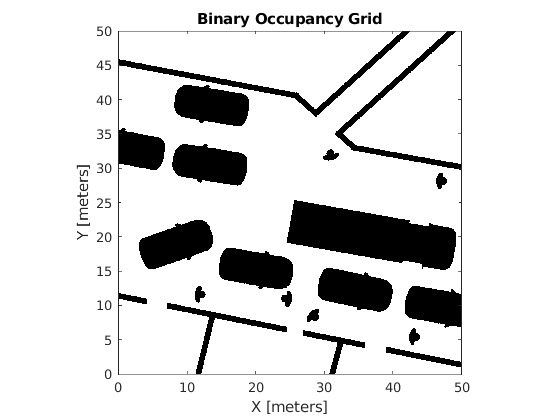

clear all
close all

% load image and create Occupancy map from image
city_occgrid = loadMap('city_map.png', 50);
show(city_occgrid)

Create costmap using vehicleCostmap function from toolbox

costmap = vehicleCostmap(city_occgrid)

costmap =   vehicleCostmap with properties:

        FreeThreshold: 0.2000
    OccupiedThreshold: 0.6500
     CollisionChecker: [1×1 driving.costmap.InflationCollisionChecker]
             CellSize: 0.0333
              MapSize: [1500 1500]
            MapExtent: [0 50 0 50]


Modify dimensions of drone and parameters of collision checker.  Drone is 0.5 m x 0.5 m.  

One circle of radius 0.5 m at the center of the drone will be used to check for collisions.

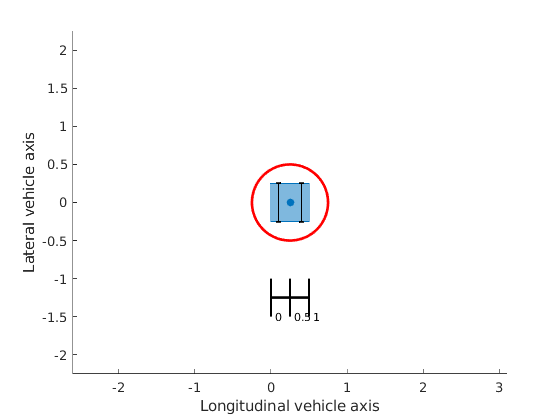

UAVdims = vehicleDimensions(0.5,0.5, 'FrontOverhang',0.1,'RearOverhang',0.1); 
numCircles = 1;
inflationRadius = 0.5;
ccConfig = inflationCollisionChecker(UAVdims, numCircles,'InflationRadius',inflationRadius);
plot(ccConfig)

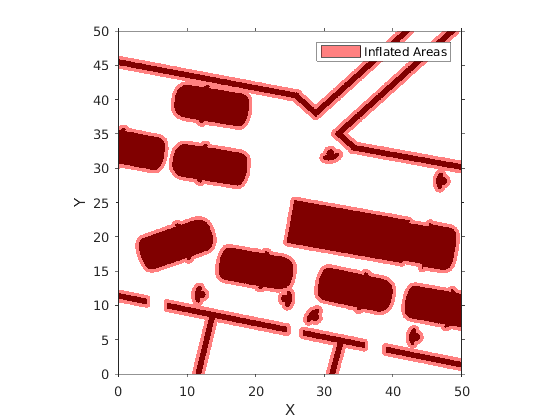


costmap.CollisionChecker = ccConfig;

figure
plot(costmap)

Run the path planner and plot on the map

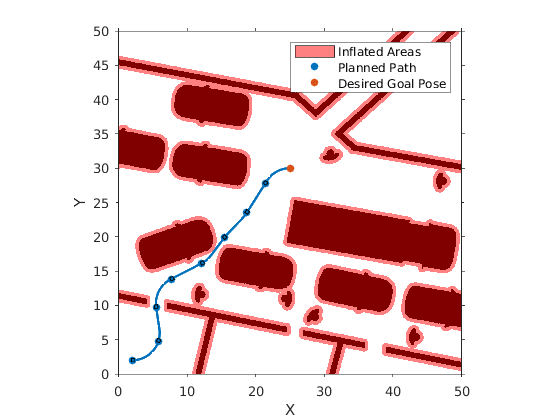

%Set the start and goal states.
start = [2,2,0];
goal = [25,30,0];

planner = pathPlannerRRT(costmap);
refPath = plan(planner,start,goal);

plot(planner)
hold on

UAVsize = 0.5;
inflated_city_occgrid = inflateMap(city_occgrid, UAVsize, 1.25)

inflated_city_occgrid =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 30
               GridSize: [1500 1500]
           XLocalLimits: [0 50]
           YLocalLimits: [0 50]
           XWorldLimits: [0 50]
           YWorldLimits: [0 50]


[time_traveled, dist_traveled, pthObj, solnInfo] = rrt(inflated_city_occgrid, start, goal)

time_traveled = 0

dist_traveled = 0

pthObj =   navPath with properties:

    StateSpace: [1×1 stateSpaceSE2]
        States: [210×3 double]
     NumStates: 210


solnInfo = struct with fields:
      IsPathFound: 1
         ExitFlag: 1
         NumNodes: 1635
    NumIterations: 8937
         TreeData: [4907×3 double]


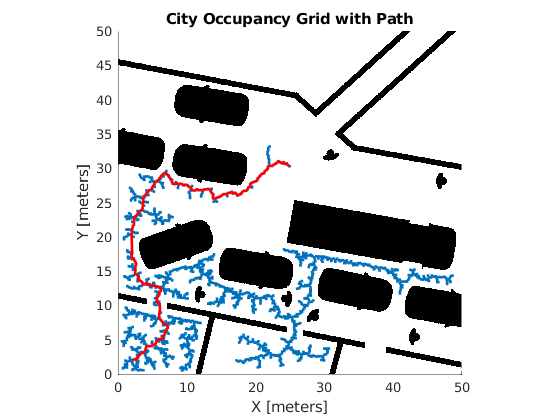

plotSolvedPath(city_occgrid,solnInfo,pthObj,'City Occupancy Grid with Path','/figures/city_path_1.png');